This is a workbook to learn how to fit a mixed effects model for the pilot data collected from Qualtrics for the EEE study. 

This is not publication quality. It is documenting my learning and thoughts. 

By Ben Graul

master = readtable('https://raw.githubusercontent.com/ben-g-1/Psyc178/main/pilot_clean.csv');
master.Pair = categorical(master.Pair);
master.Image = categorical(master.Image);
master.subj = categorical(master.subj);
master.val_type = categorical(master.val_type);
master.Half = categorical(master.Half);
master.group = categorical(master.group);
master.img_rate = master.img_rate - 50;
master.exp_rate = master.exp_rate - 50;
master.Valence_mean = master.Valence_mean - 50;
master.cue_observed_mean = master.cue_observed_mean - 50;

What do the data look like? We care about the rating that participants gave to an image after seeing a cue type. 

hicue_val = (master.img_rate(master.highcue_indx == 1));
locue_val = (master.img_rate(master.highcue_indx == -1));
master.highcue_indx = categorical(master.highcue_indx);


data_to_plot = {hicue_val, locue_val};
colors = seaborn_colors(2);

% create_figure('Violins'); hold on; 
barplot_columns(data_to_plot, 'Cue Effect on Valence Rating', 'colors', colors, 'MarkerSize', 0.5, ...
    'names', {'Hi Cue', 'Low Cue'});

Col   1: Hi Cue	Col   2: Low Cue	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error      T           P         Cohens_d
    ___________    __________    _________    ______    __________    ________

    {'Hi Cue' }      4.8393       0.48921      9.892    2.2204e-15     0.15767
    {'Low Cue'}     0.65485       0.48407     1.3528        0.1762    0.021563



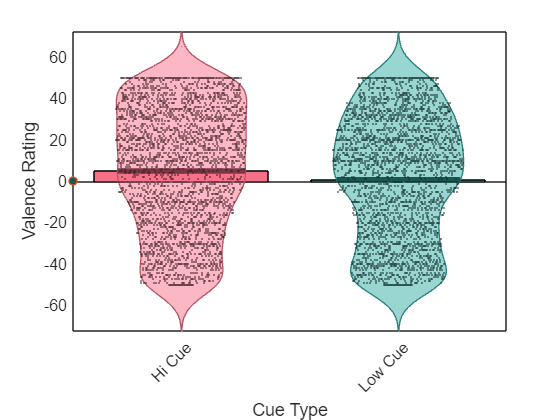

ylabel('Valence Rating')
xlabel('Cue Type');

drawnow
% hold off;
% close

This takes an extremely long time in a live script- apparently there's a known bug where figures with many points slow live scripts down considerably. It's been crashing my session sometimes. It often causes a 'graphics timeout', but that error takes >30 minutes to show up sometimes before popping up in triplicate. 

**Note on the following: **

**I now know that the p-value comparison of lmes is less important than starting with a theoretically-driven model.**

Let's start off with a very simple regression for predicting the valence score from the normative OASIS valence ratings.

We'll include a positive control for something that should have no relationship with the ratings for a sanity check.  

lme1 = fitlme(master, 'img_rate ~ Valence_mean')

lme1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Valence_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    69206    69227    -34600           69200   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE           tStat     DF      pValue        Lower      Upper  
    {'(Intercept)' }        -3.1905       0.22806    -13.99    7870    6.0177e-44    -3.6376    -2.7435
    {'Valence_mean'}         1.0393     0.0097856    106.21    7870             0     1.0202     1.0585

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        19.617      1


badlme = fitlme(master, 'img_rate ~ Half')

badlme = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    img_rate ~ 1 + Half

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    76205    76226    -38099           76199   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF      pValue       Lower      Upper 
    {'(Intercept)'}         2.4754     0.48771     5.0755    7870    3.954e-07     1.5193    3.4314
    {'Half_2'     }        0.54345     0.68973    0.78791    7870      0.43077    -0.8086    1.8955

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        30.598      30.124    31.079


 It looks like there's a strong connection between these subject valence ratings and the OASIS valence ratings. This is not surprising. 

What if we add in the variable of interest? 

lme2 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx');
compare(lme1, lme2); %sig 

This produces a significant improvement.  

Can we improve by adding subjects as a random effect? 

lme3 = fitlme(master, 'img_rate ~ Valence_mean + highcue_indx + (1|subj)');
compare(lme2, lme3, 'CheckNesting', true); %sig 

This was also a significant improvement. 

The computing time increases dramatically (seconds vs many minutes) once I start adding in random effects.

What about if we cross the fixed effect as well?

lme4 = fitlme(master, 'img_rate ~ Valence_mean * highcue_indx + (1|subj)')

lme4 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           4
    Random effects coefficients        123
    Covariance parameters                2

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + (1 | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    68756    68798    -34372           68744   

Fixed effects coefficients (95% CIs):
    Name                                   Estimate     SE          tStat      DF      pValue        Lower        Upper   
    {'(Intercept)'                }          -5.2528     0.56305    -9.3292    7868    1.3618e-20      -6.3566     -4.1491
    {'highcue_indx_1'             }           4.1248     0.43697     9.4394    7868    4.8448e-21       3.2682      4.9813
    {'Valence_mean'               }           1.0347    0.013261     78.025    7868 

compare(lme3, lme4, 'CheckNesting', true); %nosig 

Doesn't seem to have any real benefit. Let's try to account for individual preference of a given image *within* each subject.

lme5 = fitlme(master, 'img_rate ~ Valence_mean * highcue_indx + (Valence_mean * highcue_indx|subj)')

lme5 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           4
    Random effects coefficients        492
    Covariance parameters               11

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + (1 + highcue_indx*Valence_mean | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67958    68062    -33964           67928   

Fixed effects coefficients (95% CIs):
    Name                                   Estimate     SE          tStat      DF      pValue         Lower        Upper   
    {'(Intercept)'                }          -5.2524     0.57897     -9.072    7868     1.4543e-19      -6.3873     -4.1175
    {'highcue_indx_1'             }           4.1239     0.40932     10.075    7868     9.9248e-24       3.3215      4.9262
    {'Valence_mean'               }           1.0349 

This was made after discussion w/ Tor 10/2/23. 

torlmm = fitlme(master, 'img_rate ~ highcue_indx + Valence_mean + Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx + (highcue_indx + Valence_mean + Valence_mean * highcue_indx + Valence_mean^2 + Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)')

torlmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        834
    Covariance parameters               24

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67181    67390    -33561           67121   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE            tStat      DF      pValue        Lower         Upper    
    {'(Intercept)'                  }            -3.7947        1.7067    -2.2235    7866      0.026212       -7.1402     -0.44921
    {'highcue_indx_1'          

Looking into notation, this can actually be simplified significantly to 

'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image) + (1 | exp_rate:Image)'

because A*B has an implicit A + B in addition to interaction effects, and A^2 includes both A and A^2

minlmm = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj)')

minlmm = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        738
    Covariance parameters               22

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67821    68016    -33883           67765   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE           tStat       DF      pValue         Lower         Upper      
    {'(Intercept)'                  }            -3.8235      0.89942     -4.2511    7866     2.1522e-05       -5.5866        -2.0604
    {'highcue_indx_1'               }             4.3889 


minlmm2 = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair)')

minlmm2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        770
    Covariance parameters               23

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67263    67465    -33602           67205   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE           tStat       DF      pValue        Lower         Upper    
    {'(Intercept)'                  }            -3.6603       1.6888     -2.1674    7866      0.030235       -6.9708     -0.34979
    {'highcue_indx_1'               }            


minlmm3 = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair:Image)')

minlmm3 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        802
    Covariance parameters               23

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67195    67397    -33569           67137   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE            tStat       DF      pValue         Lower         Upper    
    {'(Intercept)'                  }            -3.8232        1.4417     -2.6519    7866      0.0080191       -6.6492     -0.99715
    {'highcue_indx_1'               }  


minlmm4 = fitlme(master, 'img_rate ~ Valence_mean^2 * highcue_indx + (Valence_mean^2 * highcue_indx|subj) + (1 | Pair) + (1 | Pair:Image)')

minlmm4 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            7872
    Fixed effects coefficients           6
    Random effects coefficients        834
    Covariance parameters               24

Formula:
    img_rate ~ 1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) + (1 + highcue_indx*Valence_mean + Valence_mean^2 + highcue_indx:(Valence_mean^2) | subj) + (1 | Pair) + (1 | Pair:Image)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    67181    67390    -33561           67121   

Fixed effects coefficients (95% CIs):
    Name                                     Estimate       SE            tStat      DF      pValue        Lower         Upper    
    {'(Intercept)'                  }            -3.7947        1.7067    -2.2235    7866      0.026212       -7.1402     -0.44921
    {'highcue_indx_1'         

Do we care about the ratings, or do we actually care about the *difference between *pairs of ratings?

Let's create a table focused on within-pair comparisons

master = sortrows(master,"Pair","ascend");

cuehl = double(master.highcue_indx);
cuemean = master.cue_observed_mean;
pair = master.Pair;
rating = master.img_rate;
stimmean = master.Valence_mean;

wh_high = cuehl == 2;
wh_low = cuehl == 1;

hi_table = master(wh_high, :);
lo_table = master(wh_low, :);

pair_table = table();
pair_table.subj = hi_table.subj;
pair_table.Pair = hi_table.Pair;
pair_table.group = hi_table.group;
pair_table.hi_val = hi_table.img_rate;
pair_table.lo_val = lo_table.img_rate;
pair_table.rating_mean = (hi_table.img_rate + lo_table.img_rate)/2;
pair_table.cue_mean = (hi_table.cue_observed_mean + lo_table.cue_observed_mean)/2;
pair_table.cue_sd = (hi_table.cue_observed_std + lo_table.cue_observed_std)/2;
pair_table.stim_mean = (hi_table.Valence_mean + lo_table.Valence_mean)/2;
pair_table.stim_sd = (hi_table.Valence_SD + lo_table.Valence_SD)/2;
pair_table.rating_diff = hi_table.img_rate - lo_table. img_rate;
pair_table.stim_diff = (hi_table.Valence_mean - lo_table.Valence_mean);
pair_table.norm_hi = pair_table.hi_val - pair_table.rating_mean;
pair_table.norm_lo = pair_table.lo_val - pair_table.rating_mean;


What do these data look like?

Col   1: Cued Rating Difference	Col   2: Normative Rating Difference	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
                 Name                  Mean_Value    Std_Error       T           P         Cohens_d 
    _______________________________    __________    _________    _______    __________    _________

    {'Cued Rating Difference'     }       4.1845      0.28442      14.712    2.2204e-15      0.23451
    {'Normative Rating Difference'}    0.0063838     0.016425     0.38865       0.69755    0.0061949



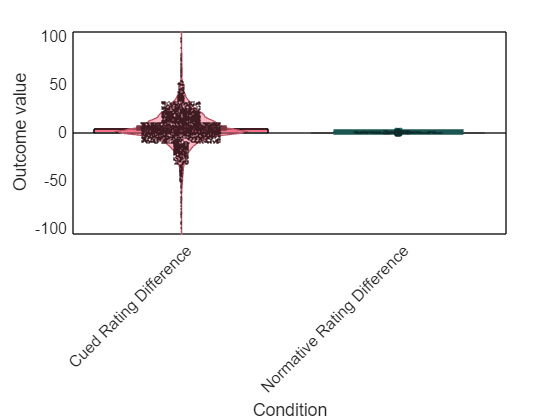

Error using text
Value should be a finite number greater than 0

Error in barplot_columns>star_plot (line 862)
    star_han(i) = text(xvals(i), yval, mystr, 'FontSize', starsize, 'FontWeight', 'b');

Error in barplot_columns (

data_to_plot = {pair_table.rating_diff pair_table.stim_diff};

% create_figure('Violins'); hold on; 
barplot_columns(data_to_plot, 'Valence Rating Difference Within Pairs', 'colors', colors, 'MarkerSize', 0.3, ...
    'names', {'Cued Rating Difference', 'Normative Rating Difference'});

ylabel('Valence Rating Hicue - locue')
xlabel('Comparison to Normative Ratings');
drawnow
hold off;

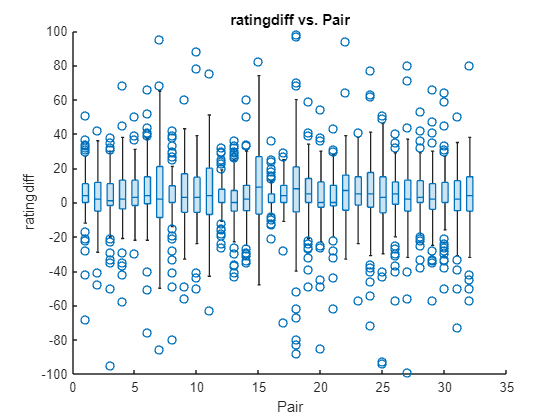



% Create boxchart of pair_table.Pair and pair_table.rating_diff
figure; hold on;
h1 = boxchart(double(pair_table.Pair),pair_table.rating_diff,"DisplayName","rating_diff");
% hold on;
% Add xlabel, ylabel, title, and legend
xlabel("Pair")
ylabel("ratingdiff")
title("ratingdiff vs. Pair")
drawnow
hold off;

It seems like outliers might be really messing this up. 

**Note: It looks like the barplot_columns function has outlier detection as well.**

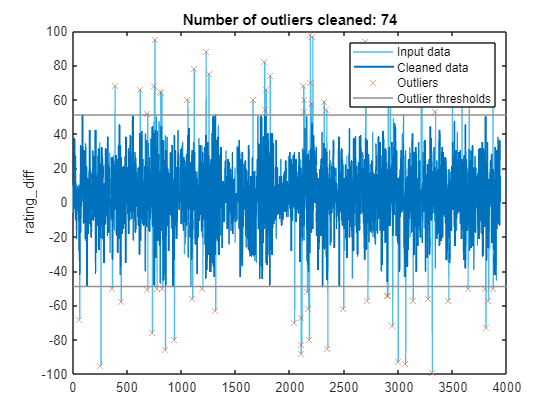

% Remove outliers
[cleanpairs,outlierIndices,~,thresholdLow,thresholdHigh] = rmoutliers(pair_table,...
    "percentiles",[1 99],"DataVariables","rating_diff");

% Display results
figure; 
plot(pair_table.rating_diff,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(find(~outlierIndices),cleanpairs.rating_diff,"Color",[0 114 189]/255,...
    "LineWidth",1.5,"DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),pair_table.rating_diff(outlierIndices),"x",...
    "Color",[217 83 25]/255,"DisplayName","Outliers")

% Plot outlier thresholds
plot([xlim missing xlim],...
    [thresholdLow.rating_diff*[1 1] NaN thresholdHigh.rating_diff*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
ylabel("rating_diff","Interpreter","none")
drawnow
hold off

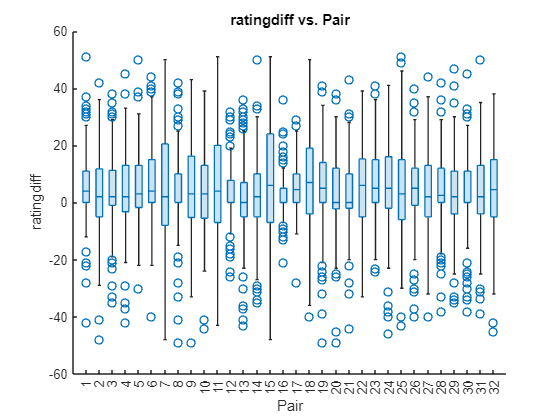


clear thresholdLow thresholdHigh

% Create boxchart of pair_table.Pair and pair_table.rating_diff
% figure; hold on;
h2 = boxchart(cleanpairs.Pair, cleanpairs.rating_diff,"DisplayName","rating_diff");

% Add xlabel, ylabel, title, and legend
xlabel("Pair")
ylabel("ratingdiff")
title("ratingdiff vs. Pair")

drawnow
% hold off;

data_to_plot = {cleanpairs.rating_diff cleanpairs.stim_diff};

% create_figure('Violins'); hold on; 
barplot_columns(data_to_plot, 'Valence Rating Difference Within Pairs', 'colors', colors, 'MarkerSize', 0.5, ...
    'names', {'Cued Rating Difference', 'Normative Rating Difference'});

Col   1: Cued Rating Difference	Col   2: Normative Rating Difference	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
                 Name                  Mean_Value    Std_Error       T           P         Cohens_d 
    _______________________________    __________    _________    _______    __________    _________

    {'Cued Rating Difference'     }       4.2361      0.24529       17.27    2.2204e-15       0.2779
    {'Normative Rating Difference'}    0.0050095     0.016568     0.30236        0.7624    0.0048654



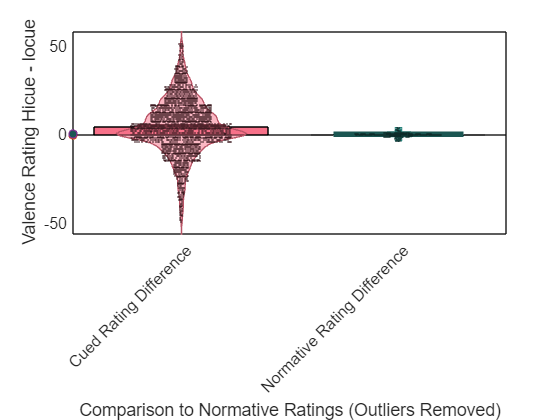

ylabel('Valence Rating Hicue - locue')
xlabel('Comparison to Normative Ratings (Outliers Removed)');

drawnow
% hold off;

**How do the LMEs compare for the difference between ratings within pair to the overall valence rating prediction?**

First, we can compare whether removing the outliers improved things.

lme9 =  fitlme(pair_table, 'rating_diff ~ stim_mean')

lme9 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3936
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rating_diff ~ 1 + stim_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    33859    33877    -16926           33853   

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE          tStat      DF      pValue        Lower        Upper   
    {'(Intercept)'}           4.1304     0.29331     14.082    3934    5.6487e-44       3.5553      4.7054
    {'stim_mean'  }        0.0094634    0.012589    0.75174    3934       0.45225    -0.015217    0.034144

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower    Upper 
    {'Res Std'}        17.84

lme10 = fitlme(cleanpairs, 'rating_diff ~ stim_mean')

lme10 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3862
    Fixed effects coefficients           2
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    rating_diff ~ 1 + stim_mean

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    32005    32024    -16000           31999   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower         Upper   
    {'(Intercept)'}          4.1703     0.25272    16.501    3860    3.6531e-59        3.6748      4.6657
    {'stim_mean'  }        0.011671    0.010827     1.078    3860       0.28112    -0.0095562    0.032899

Random effects covariance parameters (95% CIs):
Group: Error
    Name               Estimate    Lower     Upper 
    {'Res Std'}        15.239

This was a improvement in all categories. 

The residual error and AIC/BIC are all much lower when looking at the rating difference. However, since we're estimating a different outcome, this might not mean much. 


lme11 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + (1|subj)')

lme11 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3862
    Fixed effects coefficients           2
    Random effects coefficients        123
    Covariance parameters                2

Formula:
    rating_diff ~ 1 + stim_mean + (1 | subj)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    32007    32032    -16000           31999   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower         Upper   
    {'(Intercept)'}          4.1703     0.25272    16.501    3860    3.6531e-59        3.6748      4.6657
    {'stim_mean'  }        0.011671    0.010827     1.078    3860       0.28112    -0.0095562    0.032899

Random effects covariance parameters (95% CIs):
Group: subj (123 Levels)
    Name1                  Name2                  Type  

lme11 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            3862
    Fixed effects coefficients           2
    Random effects coefficients         32
    Covariance parameters                2

Formula:
    rating_diff ~ 1 + stim_mean + (1 | Pair)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    32007    32032    -16000           31999   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF      pValue        Lower         Upper   
    {'(Intercept)'}          4.1703     0.25272    16.501    3860    3.6531e-59        3.6748      4.6657
    {'stim_mean'  }        0.011671    0.010827     1.078    3860       0.28112    -0.0095562    0.032899

Random effects covariance parameters (95% CIs):
Group: Pair (32 Levels)
    Name1                  Name2                  Type   

lme12 = fitlme(cleanpairs, 'rating_diff ~ stim_mean + (1|Pair)')


Questions:

How can I  verify the model accuracy?

Would trying to make a predictive model for some participants left out be a good next step?

Will this be useful to apply to my patient population by adding in iEEG signal?